#### Load data

load('SR_A0.04_f0.50_2.mat');
SX=X;SY=-Y; % snake data points

### Original data plot

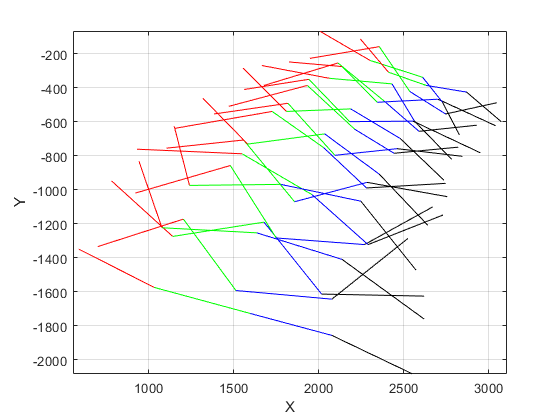

[~,n]=size(X);
for i=1:n
    plot(X(1:2,i),-Y(1:2,i),'r');
    hold on
    plot(X(2:3,i),-Y(2:3,i),'g');
    plot(X(3:4,i),-Y(3:4,i),'b');
    plot(X(4:5,i),-Y(4:5,i),'k');
end
hold off
axis equal
grid on
xlabel('X')
ylabel('Y')

#### Bounding box points

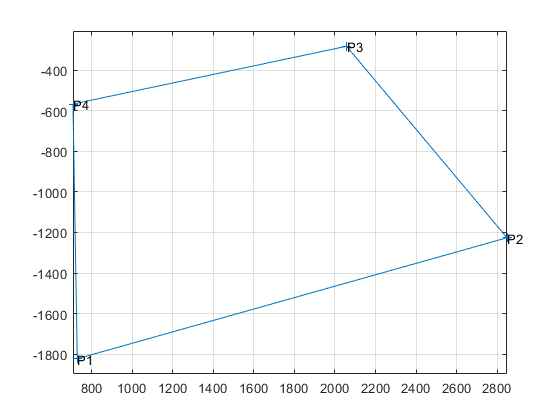

I=[1,7,9,3];
P=[xr(I); ...
    -yr(I)];

while true
    if dot((P(:,1)-P(:,2))/norm(P(:,1)-P(:,2)),...
            (P(:,3)-P(:,4))/norm(P(:,3)-P(:,4))) ~= 1
        break
    end
end
plot([P(1,:) P(1,1)],[P(2,:) P(2,1)],'+-');
for i=1:4
    text(P(1,i),P(2,i),strcat('P',num2str(i)))
end
grid on
axis equal

#### Calculate edge equations

$$P_i P_{\text{mod}(i,4)+1$$ gives a1*x+b*y+c1=0, P3P4 gives a2*x+b2*y+c2=0

AB=zeros(2,4);
syms a1 b1
for i=1:4
    eq1=a1*P(1,i)+b1*P(2,i)+1==0;
    eq2=a1*P(1,mod(i,4)+1)+b1*P(2,mod(i,4)+1)+1==0;
    [y1,y2]=solve([eq1,eq2],[a1,b1]);
    AB(:,i)=double([y1,y2]');
end

#### Calculate horizon points A,B

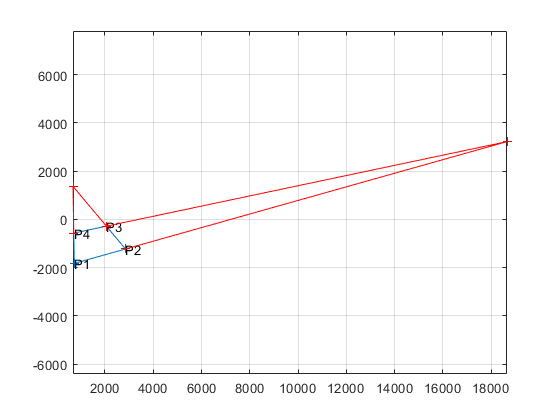

eq1=a1*AB(1,1)+b1*AB(2,1)+1==0; % line p1p2
eq2=a1*AB(1,3)+b1*AB(2,3)+1==0; % line p3p4
[y1,y2]=solve([eq1,eq2],[a1,b1]);
A=double([y1,y2]');

eq1=a1*AB(1,2)+b1*AB(2,2)+1==0; % line p2p3
eq2=a1*AB(1,4)+b1*AB(2,4)+1==0; % line p4p1
[y1,y2]=solve([eq1,eq2],[a1,b1]);
B=double([y1,y2]');

plot([P(1,:) P(1,1)],[P(2,:) P(2,1)],'+-');
for i=1:4
    text(P(1,i),P(2,i),strcat('P',num2str(i)))
end
hold on
plot([A(1),P(1,3)],[A(2),P(2,3)],'r-+')
plot([A(1),P(1,2)],[A(2),P(2,2)],'r-+')
plot([B(1),P(1,4)],[B(2),P(2,4)],'r-+')
plot([B(1),P(1,3)],[B(2),P(2,3)],'r-+')
hold off
grid on
axis equal

#### Identify Principle Axes

Find $$P_i$$ such at $$\overline{AP_i}\cdot\overline{BP_i}$$ is maximum. Then define $$\overline{P_i P_{\text{mod(i,4)}+1}}$$ as the X axis and $$\overline{P_i P_{\text{mod}(i+2,4)+1}}$$ is the Y axis.

d=zeros(1,4);
for i=1:4
    d(1,i)=dot((A-P(:,i))/norm(A-P(:,i)),...
        (B-P(:,i))/norm(B-P(:,i)));
end
[~,d]=max(d)

d = 1

X & Y axis vectors

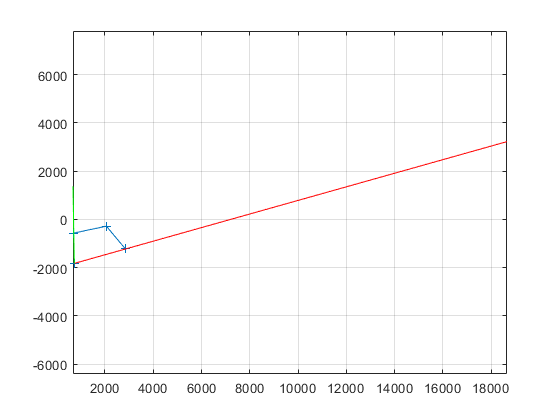

l1=P(:,mod(d,4)+1)-P(:,d);
l1=l1/norm(l1);
AP=A-P(:,d);
AP=AP/norm(AP);
BP=B-P(:,d);
BP=BP/norm(BP);
A_angle=acos(dot(l1,AP));
if A_angle<.01 || A_angle> pi-.01
    X=A;
    Y=B;
else
    X=B;
    Y=A;
end
plot([P(1,:) P(1,1)],[P(2,:) P(2,1)],'+-');
hold on
plot([P(1,d),X(1)],[P(2,d),X(2)],'r')
plot([P(1,d),Y(1)],[P(2,d),Y(2)],'g')
hold off
grid on
axis equal

#### Define Axes

Define essential points vector [P0 Pd X Y]

- P0 the origin

- Pd the known diagonal point with which we define the scale of the projection

- X (intersection point of the X axis

- Y (intersection point of the Y axis

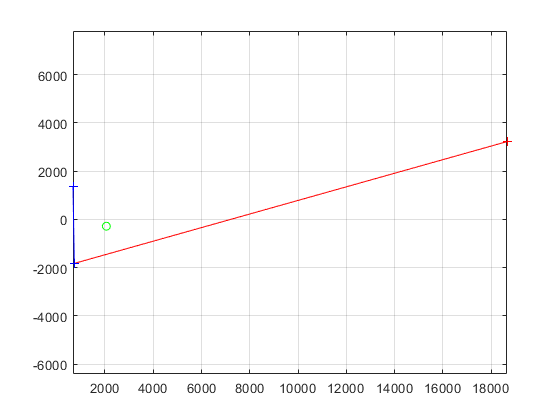

PP=[P(:,d) P(:,mod(d+1,4)+1) X Y];
plot([PP(1,1) PP(1,3)],[PP(2,1) PP(2,3)],'+-r');
hold on
plot([PP(1,1) PP(1,4)],[PP(2,1) PP(2,4)],'+-b');
plot(PP(1,2),PP(2,2),'go')
hold off
grid on
axis equal

#### Define lines originating from X and Y points

$x(t)=X+t(P_0-X)$ and $y(t)=Y+t(P_0-Y), \forall t\geq 0$

syms t a b
% t meet X axis
eq1=a*PP(1,4)+b*PP(2,4)+1==0; % Y point
eq2=a*PP(1,2)+b*PP(2,2)+1==0; % d Point
eq3=a*(PP(1,3)+t*(PP(1,1)-PP(1,3)))+...
    b*(PP(2,3)+t*(PP(2,1)-PP(2,3)))+1==0; % point on POX
[~,~,tx]=solve([eq1 eq2 eq3],[a b t]); % solve for tx

% t meet Y axis
eq1=a*PP(1,3)+b*PP(2,3)+1==0; % X point
eq2=a*PP(1,2)+b*PP(2,2)+1==0; % d Point
eq3=a*(PP(1,4)+t*(PP(1,1)-PP(1,4)))+...
    b*(PP(2,4)+t*(PP(2,1)-PP(2,4)))+1==0; % point on POY
[~,~,ty]=solve([eq1 eq2 eq3],[a b t]); % solve for ty

if ty<0 || tx<0
    disp('Error, point outside')
else
    disp('Valid point')
end

Valid point


#### Define axis scale

Define general scaling of the axis as


$$x= \frac{\alpha_x}{|AP|}+\beta_x$$



$$y= \frac{\alpha_y}{|BP|}+\beta_y$$


The difference of x coordinate between P0 and the projection of Pd on X is, say, L. So we have


$$\alpha_x= L \left(\frac{1}{|AP_d|}-\frac{1}{|AP_0|}\right)^{-1}$$



$$\beta_x =\frac{L|AP_d|}{|AP_d|-|AP_0|}$$


Assume L=0.315 m. Then we can calculate ax and bx

L=.9144; % this distance is 2x the tile width in meters (check)
px(t)=PP(:,3)+t*(PP(:,1)-PP(:,3));
ax=double(L/(1/norm(px(0)-px(tx))-1/norm(px(0)-px(1))));
bx=double(L*norm(px(0)-px(tx))/(norm(px(0)-px(tx))-norm(px(0)-px(1))));

% test (should be close to 0.315)
double(ax/norm(px(0)-px(tx))+bx)

ans = 0.9144

Similarly,  calcualte ay, by

py(t)=PP(:,4)+t*(PP(:,1)-PP(:,4));
ay=double(L/(1/norm(py(0)-py(ty))-1/norm(py(0)-py(1))));
by=double(L*norm(py(0)-py(ty))/(norm(py(0)-py(ty))-norm(py(0)-py(1))));

% test (should be close to 0)
double(ay/norm(py(0)-py(1))+by)

ans = 6.9599e-17

#### Project to Cartesian system with unit length between points

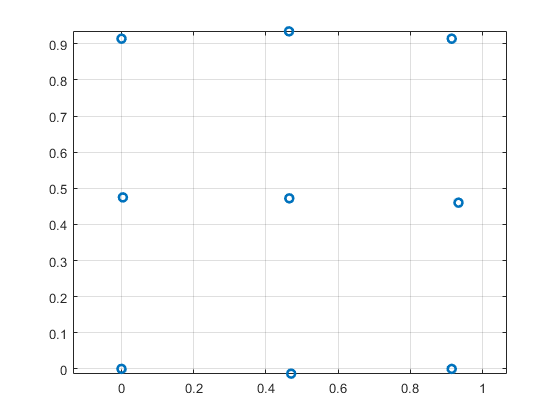

PN=[xr; -yr];
[~,n]=size(PN);
PXY=zeros(2,n);

syms t a b
% t meet X axis
eq1=a*PP(1,4)+b*PP(2,4)+1==0; % Y point
eq3=a*(PP(1,3)+t*(PP(1,1)-PP(1,3)))+...
    b*(PP(2,3)+t*(PP(2,1)-PP(2,3)))+1==0; % point on POX
for i=1:n
    eq2=a*PN(1,i)+b*PN(2,i)+1==0; % d Point
    [~,~,tx]=solve([eq1 eq2 eq3],[a b t]); % solve for tx
    PXY(1,i)=double(ax/norm(px(0)-px(tx))+bx);
end

% t meet Y axis
eq1=a*PP(1,3)+b*PP(2,3)+1==0; % X point
eq3=a*(PP(1,4)+t*(PP(1,1)-PP(1,4)))+...
    b*(PP(2,4)+t*(PP(2,1)-PP(2,4)))+1==0; % point on POY
for i=1:n
    eq2=a*PN(1,i)+b*PN(2,i)+1==0; % d Point
    [~,~,ty]=solve([eq1 eq2 eq3],[a b t]); % solve for ty
    PXY(2,i)=double(ay/norm(py(0)-py(ty))+by);
end
%plot showing mapped points to XY coord system
% you can see it is a grid
plot(PXY(1,:),PXY(2,:),'o','LineWidth',2)
axis equal
grid on

### Project Snake data points

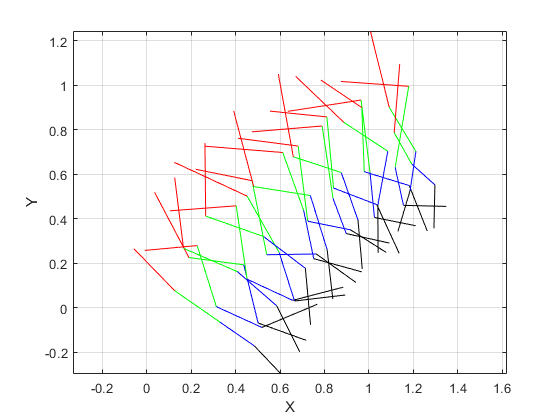

[m,n]=size(SX);
SPX=zeros(m,n); % projected X coords
SPY=zeros(m,n); % projected Y coords

syms t a b
% t meet X axis
eq1=a*PP(1,4)+b*PP(2,4)+1==0; % Y point
eq3=a*(PP(1,3)+t*(PP(1,1)-PP(1,3)))+...
    b*(PP(2,3)+t*(PP(2,1)-PP(2,3)))+1==0; % point on POX
for i=1:m % snake points
    for j=1:n % time instaces
        eq2=a*SX(i,j)+b*SY(i,j)+1==0; % d Point
        [~,~,tx]=solve([eq1 eq2 eq3],[a b t]); % solve for tx
        SPX(i,j)=double(ax/norm(px(0)-px(tx))+bx);
    end
end

% t meet Y axis
eq1=a*PP(1,3)+b*PP(2,3)+1==0; % X point
eq3=a*(PP(1,4)+t*(PP(1,1)-PP(1,4)))+...
    b*(PP(2,4)+t*(PP(2,1)-PP(2,4)))+1==0; % point on POY
for i=1:m % snake points
    for j=1:n % time instaces
        eq2=a*SX(i,j)+b*SY(i,j)+1==0; % d Point
        [~,~,ty]=solve([eq1 eq2 eq3],[a b t]); % solve for ty
        SPY(i,j)=double(ay/norm(py(0)-py(ty))+by);
    end
end

% plot resutls

for i=1:n
    plot(SPX(1:2,i),SPY(1:2,i),'r');
    hold on
    plot(SPX(2:3,i),SPY(2:3,i),'g');
    plot(SPX(3:4,i),SPY(3:4,i),'b');
    plot(SPX(4:5,i),SPY(4:5,i),'k');
end
hold off
axis equal
grid on
xlabel('X')
ylabel('Y')

### Spline plot

This gives a more snake-like appearnce to the data plot

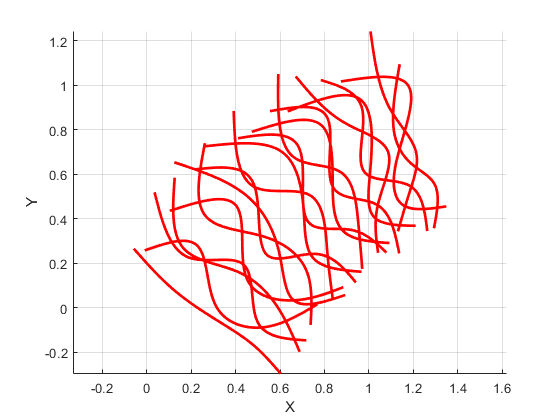

clf;
hold on;
for i=1:n
    fnplt(cscvn([SPX(:,i)';SPY(:,i)']),'r',2)
end
hold off
axis equal
grid on
xlabel('X')
ylabel('Y')